# Pressure-Volume Diagrams

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

This script will investigate pressure-volume (PV) diagrams and their relationship to state equations in a closed system.

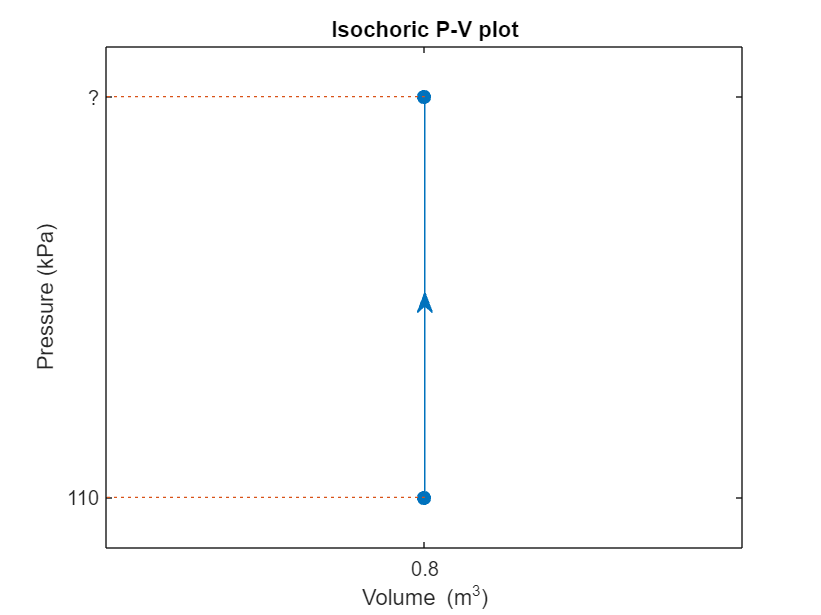  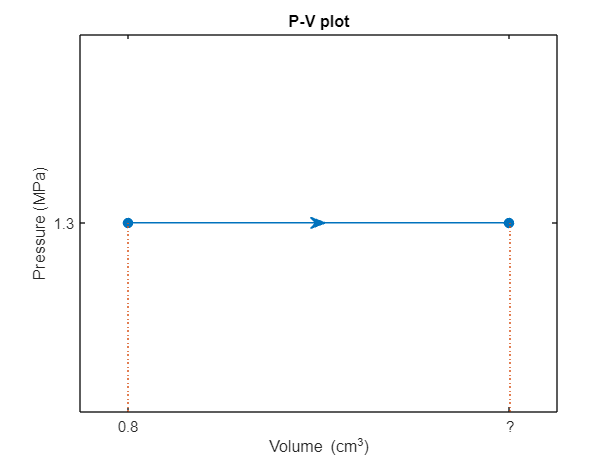  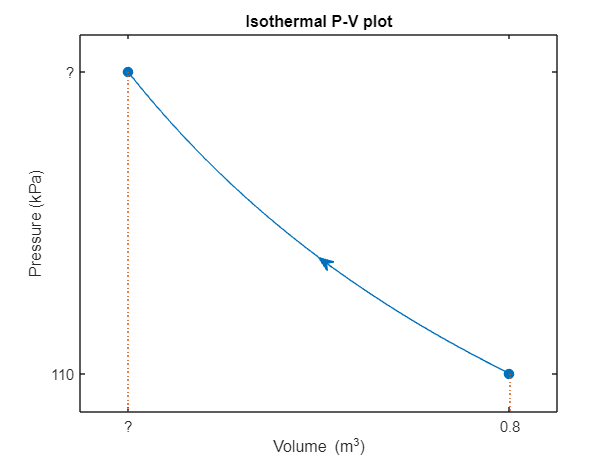

Different process paths on a pressure-volume plot express different scenarios.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane. This code uses a function `pvPlot` located in the HelperFunctions folder in this folder. 

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

## Why Would Anyone Make a Pressure-Volume plot?

Consider the expansion or compression of a gas in a piston/cylinder device. The *state variables* of pressure, volume, and temperature are all related by equations of state. One such equation of state is the ideal gas law:

$PV = nR_uT$, 

where $P$ is pressure in Pa = N/$\text{m}^2$, 

          $V$ is volume in $\text{m}^3$, 

          $n$ is moles of the gas, 

          $R_u$ is the gas constant in J/mol/K, and $%$

          $T$ is the temperature in K. 

As the volume decreases or the temperature increases, the pressure will increase. As the volume increases or the temperature decreases, the pressure will decrease. A pressure-volume (P-V) diagram can be drawn for a process in quasi-equilibrium.

## Creating P-V diagrams: Example

Consider a frictionless piston-cylinder device containing 0.8 cubic meters of air at 110 kPa and 75C. Sketch the P-V diagram in each of the following cases:

### ** Added heat, free expansion**

a) Heat is added to the system, which is allowed to expand freely.

#### **Step 1: Identify key words and translate the statement into thermodynamic terminology**

    ***Heat is added*** to the system, which is allowed to ***expand freely***.

Because heat is being added to the system, we can conclude that the temperature $T$ will go up, but because the system was at a constant pressure before, it will stay at a constant pressure. A system with constant pressure is called *isobaric**.*

The temperature will increase, and the volume will change in this isobaric system.

#### **Step 2: Identify and state necessary assumptions**

    Assumption 1: The expansion occurs in quasi-equilibrium.

    Assumption 2: Air can be treated as an ideal gas at these temperatures and pressures.

Therefore, to satisfy 

$PV = nR_uT$, 

the free expansion means the volume will go up as the temperature goes up, so the ratio will stay constant:

$\frac{V}{T} = \text{constant} = \frac{nR_u}{P_0}$, 

where $P_0$ = 110 kPa. Since we do not know the total amount of heat added, we can choose a final value, such as $V = 1.4$ cubic meters, to depict this system qualitatively. Still, since we estimated that value, we should indicate that the result is qualitative on the plot by not labeling the endpoint with a value.

% pvPlot is a local function for plotting P-V data in HelperFunctions
% You can see the code by running 

% Or you can see the documentation by running

% Run this section to visualize the P-V plot for this scenario
 
pvPlot([0.8 1.4],"m^3",[110 110],"kPa", ...
    Title="Isobaric P-V plot",LabelEndpoint=false);

### ** Added heat, constant volume**

b) Heat is added to the system while the piston is locked rigidly in place.

#### **Step 1: Identify key words and translate the statement into thermodynamic terminology**

    ***Heat is added*** to the system while the piston is ***locked rigidly in place***. 

The added heat means that the temperature will rise. The fact that the piston is locked rigidly in place means that the volume cannot change. A constant volume system is called *isochoric*.

The temperature in this isochoric system will increase. 

#### **Step 2: Identify and state necessary assumptions**

    Assumption 1: The expansion occurs in quasi-equilibrium.

    Assumption 2: Air can be treated as an ideal gas at these temperatures and pressures.

Because heat is added to an isochoric system in quasi-equilibrium, 

$PV_0 = nR_uT$ $\Rightarrow$ $\frac{P}{T} = \frac{nR_u}{V_0}$,

where $V_0$ is 0.8 cubic meters. This means that the temperature and pressure will both increase while the volume is constant. Since we do not know the total amount of heat added, we can choose a final value such as $P = 185$ kPa to depict this system qualitatively. Still, since we estimated that value, we should indicate that such a result is qualitative on the plot by not labeling the endpoint with a value.

 
pvPlot([0.8 0.8],"m^3",[110,185],"kPa",Title="Isochoric P-V plot",LabelEndpoint=false);

### ** Constant temperature**

c) Use the piston to compress the air in the cylinder isothermally until it reaches a volume of 0.5 cubic meters.

#### **Step 1: Identify key words and translate the statement into thermodynamic terminology**

    Use the piston to ***compress the air*** in the cylinder ***isothermally*** until it reaches a ***volume of 0.5 cubic meters***.

Because the air is compressed, that means the volume is decreasing. Isothermal means that this system is evolving at a constant temperature. We are also given a known final volume of 0.5 m$^3$, at which the compression will cease.

A piston compresses air from 0.8 m$^3$ and 110 kPa to 0.5 m$^3$ at a constant temperature of 75C.

#### **Step 2: Identify and state necessary assumptions**

    Assumption 1: The expansion occurs in quasi-equilibrium.

    Assumption 2: Air can be treated as an ideal gas at these temperatures and pressures.

The ideal gas law is:

$PV = nR_uT$, 

where $P$ is pressure in Pa = N/$\text{m}^2$, 

          $V$ is volume in $\text{m}^3$, 

          $n$ is moles of the gas, 

          $R_u$ is the gas constant in J/mol/K, and $%$

          $T$ is the temperature in K. 

Because we are assuming quasi-equilibrium and isothermal compression, the right side of the equation will be constant, so we have


$$P_0V_0 = nR_uT_0 = \text{constant}$$


$PV = P_0V_0 = 0.8*(110,000) = 88,000$ Joules

If we work in kJ and kPa, this becomes

                                 $P = \frac{88}{V}$.                          $(\star)$

Define a vector of volume values,

vValues = 0.8:-0.01:0.5;

use equation $(\star)$ to define a corresponding vector of pressure values,

pValues = 88./vValues;

then plot the curve using `pvPlot`.

 
pvPlot(vValues,"m^3",pValues,"kPa",Title="Isothermal P-V plot",flag=true);

### ** Exercise: Sketch a P-V diagram**

A rigid tank contains 750 ccs of air at 450 kPa and 125 C. Heat is transferred out of the system into the surroundings. Sketch the P-V plot for the air in the tank in this scenario. Remember to state any required assumptions relevant to your solution.

### Solution

Assumption 1: 'Rigid tank' means the system is isochoric.

Assumption 2: 'Heat is transferred out' means that the temperature of the system is decreasing.

Assumption 3: The contraction occurs in quasi-equilibrium.

pvPlot([750 750],"cm^3",[450 320],"kPa",LabelEndpoint=false);

 **Reflect**.

- How is Exercise 1 related to Example 1b?

- What scenario could result in the following P-V plot?

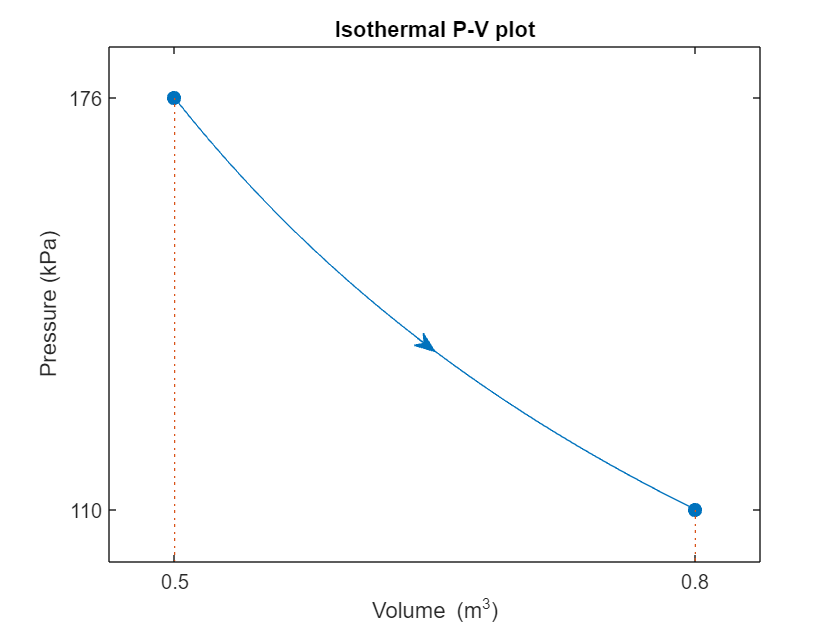

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## **Definitions**

  **State variables**

A state variable is a value that depends only on the state of a system and not on the path a process took to reach that state.

Return to text

  **Quasi-equilibrium**

A system is in quasi-equilibrium if the process changes happen much more slowly than the rate at which thermodynamic equilibrium is re-established in a new state. In this case, the system can be considered consistently in thermodynamic equilibrium at each point for purposes of calculus as smooth infinitesimal change. This idealized simplification is practical for computation and can be thought of as constant-voltage batteries, zero-resistance wires, or frictionless pulleys.

Return to text

  **Isothermal: **constant temperature

This contrasts with **adiabatic**. An adiabatic process is isolated from the environment, so no heat is added or removed from the system. An isothermal process is embedded in its environment such that whatever heat flow is required to keep a constant temperature in the system occurs. 

  **Isobaric:** constant pressure

  **Isochoric: **constant volume

This is also called isovolumetric. 

  **Adiabatic: **thermally isolated, no heat flow

This is the result when the boundary of your system is a perfect thermal insulator. This contrasts with **isothermal**, when the boundary of your system is perfectly porous to heat such that a constant temperature is maintained.